close all
clear
clc

syms x y t r z real
syms e n mu beta mu_0 epsilon_0 omega real positive
syms pi

% Computed parameters
c_0=1/sqrt(epsilon_0*mu_0);
v=beta*c_0;
epsilon=n^2*epsilon_0;

% Andrades' term
k_r=omega/v*sqrt(1-beta^2*n^2);

% Analytical solution in cylindrical coordinates (without limit of Bessel function)
Er=+e*abs(omega)/(2*pi*epsilon*v^2)*...
    sqrt(1-beta^2*n^2)*besselk(1,k_r*r).*...
    exp(-1i*omega*z/v);
Ez=+e*abs(omega)/(2*pi*epsilon*v^2)*...
    1i*(1-beta^2*n^2)*besselk(0,k_r*r).*...
    exp(-1i*omega*z/v);
Hp=+e*abs(omega)/(2*pi*v)*...
    sqrt(1-beta^2*n^2)*besselk(1,k_r*r).*...
    exp(-1i*omega*z/v);

% % Analytical solution in cylindrical coordinates (with limit of Bessel function)
% Er=+e/(2*pi*epsilon*v)*...
%     sqrt(1i*pi*abs(k_r)./(2*r)).*...
%     exp(-1i*(abs(k_r)*r+omega*z/v));
% Ez= -e/(2*pi*epsilon*v)*...
%     sqrt(1i*pi*abs(k_r)*(beta^2*n^2-1)./(2*r)).*...
%     exp(-1i*(abs(k_r)*r+omega*z/v));
% Hp= +e/(2*pi)*...
%     sqrt(1i*pi*abs(k_r)./(2*r)).*...
%     exp(-1i*(abs(k_r)*r+omega*z/v));

% Impose analytical solution
H= subs(Hp,[r,z],[abs(y),x]).*sign(y)

$$H = \frac{e\,\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,{\mathrm{e}}^{-\frac{\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,x\,\mathrm{i}}{\beta }}\,\mathrm{sign}\left(y\right)\,K_{1}\left(\frac{\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,\left|y\right|\,\sqrt{1-\beta^{2}\,n^{2}}}{\beta }\right)\,\sqrt{1-\beta^{2}\,n^{2}}}{2\,\beta \,\pi }$$

E=[subs(Ez,[r,z],[abs(y),x])
   subs(Er,[r,z],[abs(y),x]).*sign(y)]

$$E = \left[\begin{array}{c} -\frac{e\,\mu_{0}\,\omega \,{\mathrm{e}}^{-\frac{\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,x\,\mathrm{i}}{\beta }}\,K_{0}\left(\frac{\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,\left|y\right|\,\sqrt{1-\beta^{2}\,n^{2}}}{\beta }\right)\,\left(\beta^{2}\,n^{2}-1\right)\,\mathrm{i}}{2\,\beta^{2}\,n^{2}\,\pi }\\ \frac{e\,\mu_{0}\,\omega \,{\mathrm{e}}^{-\frac{\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,x\,\mathrm{i}}{\beta }}\,\mathrm{sign}\left(y\right)\,K_{1}\left(\frac{\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,\left|y\right|\,\sqrt{1-\beta^{2}\,n^{2}}}{\beta }\right)\,\sqrt{1-\beta^{2}\,n^{2}}}{2\,\beta^{2}\,n^{2}\,\pi } \end{array}\right]$$

j=[+e/(pi*abs(y))*dirac(y)*exp(-1i*omega/v*x) % Differs from equation (2.36) by a factor 1/2
   0]

$$j = \left[\begin{array}{c} \frac{e\,{\mathrm{e}}^{-\frac{\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,x\,\mathrm{i}}{\beta }}\,\delta (y)}{\pi \,\left|y\right|}\\ 0 \end{array}\right]$$

% Additional variables to compute residuals
X=[x,y];
mu=mu_0;
assume(beta^2*n^2>1)

% Check residual of magnetic field
R_H=simplify(...
    1i*mu*omega*H...
    +mycurl(E,X))

$$R\_H = 0$$

% Check residual of electric field
% CONSIDER THAT Y/SIGN(Y)=ABS(Y) (OR Y*SIGN(Y)=ABS(Y))
R_E=simplify(...
    1i*epsilon*omega*E...
    -mycurl(H,X)...
    +j)

$$R\_E = \left[\begin{array}{c} \frac{e\,\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,{\mathrm{e}}^{-\frac{\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,x\,\mathrm{i}}{\beta }}\,\mathrm{sign}\left(y\right)\,K_{1}\left(\frac{\sqrt{\epsilon_{0}}\,\sqrt{\mu_{0}}\,\omega \,\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta }\right)\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{2\,\beta \,y\,\pi }\\ 0 \end{array}\right]$$

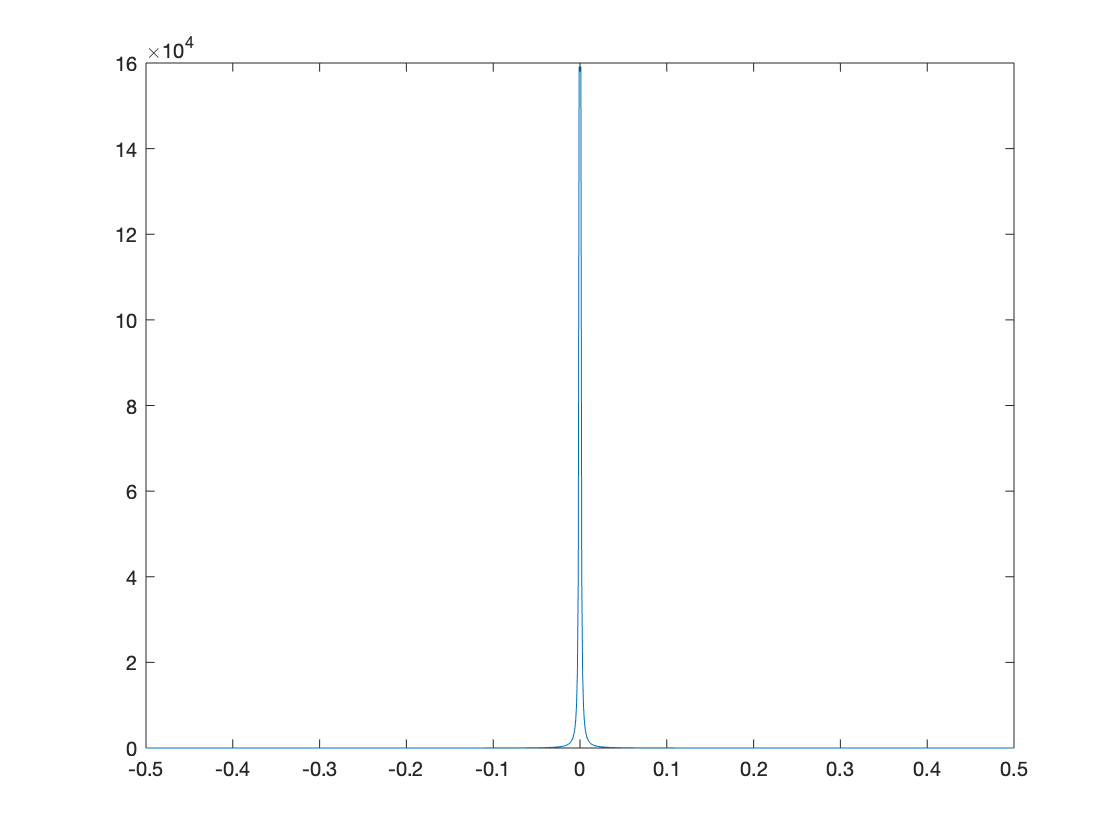

% Plot residual
omega=1; e=1; beta=1; mu_0=1; epsilon_0=1; n=2; epsilon_0=n^2*epsilon_0; pi=3.141592653589793;
x=0; y=linspace(-1/2,+1/2,1001);
plot(y,eval(R_E(1)))